# EN2570 - Digital Signal Processing

` Design Project`

## Design of a Finite Duration Impulse Response (FIR)

## Bandpass Filter

Name : Rathnayaka R.G.H.V.

Index Number : 180529E

## Prescribed Filter Specifications

A = 5;
B = 2;
C = 9;

A_P = 0.03+0.01*A; %maximum passband ripple (dB)
A_a = 45+B; %minimum stopband attenuation (dB)
wp1 = C*100+300; %lower passband edge (rad/s)
wp2 = C*100+700; %upper passband edge (rad/s)
wa1 = C*100+150; %lower stopband edge (rad/s)
wa2 = C*100+800; %upper stopband edge (rad/s)
ws = 2*(C*100+1200); %sampling freqency (rad/s)

## Derived Filter Specifications

Bt1 = wp1-wa1; %lower transition width (rad/s)
Bt2 = wa2-wp2; %upper transisiton width (rad/s)
Bt = min(Bt1,Bt2); %critical transition width (rad/s)
wc1 = wp1-Bt/2; %lower cutoff frequency (rad/s)
wc2 = wp2+Bt/2; %upper cutoff frequency (rad/s)
T = 2*pi/ws; %sampling period (s)

## Kaiser Window Parameters

delta_P = (10^(0.05*A_P) - 1)/ (10^(0.05*A_P) + 1); %computing deltaP
delta_A = 10^(-0.05*A_a); %computing deltaA
delta = min(delta_P,delta_A); %computing delta

Aa = -20*log10(delta); %Actual stopband attenuation

if Aa <= 21 %Calculating alpha 
    alpha = 0;
elseif Aa > 21 && Aa <= 50
    alpha = 0.5842*(Aa-21)^0.4 + 0.07886*(Aa-21);
else
    alpha = 0.1102*(Aa-8.7);
end

if Aa <= 21 %Calculating D
    D = 0.9222;
else
    D = (Aa-7.95)/14.36;
end

N = ceil(ws*D/Bt +1); %Order of the filter
if mod(N,2) == 0
    N = N+1;
end

n = -(N-1)/2:1:(N-1)/2; %Length of the filter

beta = alpha*sqrt(1-(2*n/(N-1)).^2); %Computing Beta

## Computing I($\alpha$)

bessel_limit = 50;
Ialpha = 1;
for k = 1:bessel_limit
    term_k = (1/factorial(k)*(alpha/2).^k).^2;
    Ialpha = Ialpha + term_k;
end

## Computing I($\beta$)

Ibeta = 1;
for k = 1:bessel_limit
    term_k = (1/factorial(k)*(beta/2).^k).^2;
    Ibeta = Ibeta + term_k;
end

## Plotting Kaiser Window

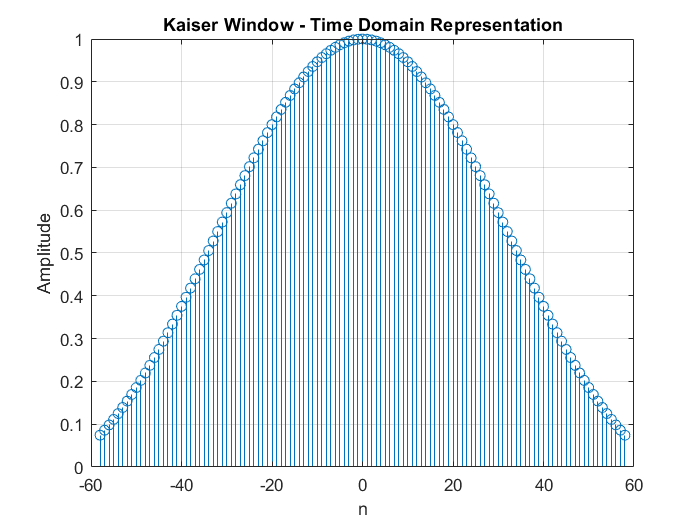

wknt = Ibeta/Ialpha;

figure
stem(n,wknt)
grid on;
xlabel('n')
ylabel('Amplitude')
title('Kaiser Window - Time Domain Representation');

## Generating Causal Impulse Response

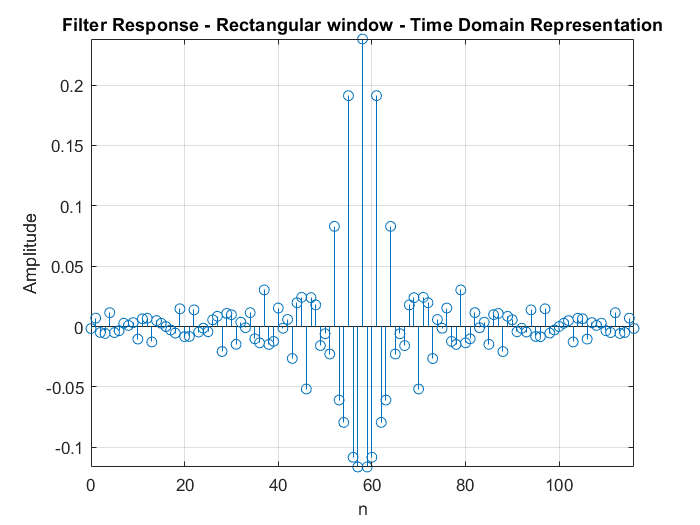

nleft = -(N-1)/2:-1;
hntleft = 1./(nleft*pi).*(sin(wc2*nleft*T)-sin(wc1*nleft*T));
nright = 1:(N-1)/2;
hntright = 1./(nright*pi).*(sin(wc2*nright*T)-sin(wc1*nright*T));
hnt0 = 2/ws*(wc2-wc1);
hnt = [hntleft,hnt0,hntright];
n_shifted = (0:1:N-1);
figure
stem(n_shifted,hnt);axis tight;
grid on;
xlabel('n')
ylabel('Amplitude')
title('Filter Response - Rectangular window - Time Domain Representation');

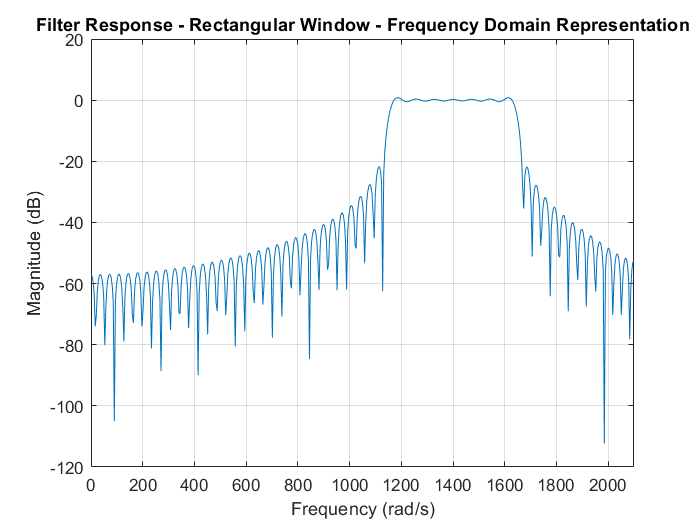


figure
[h,w] = freqz(hnt);
w = w/T;
h = 20*log10(abs(h));
plot(w,real(h))
axis([0,2100,-120,20]);
grid on;
xlabel('Frequency (rad/s)')
ylabel('Magnitude (dB)')
title('Filter Response - Rectangular Window - Frequency Domain Representation');

## Applying the window to the filter

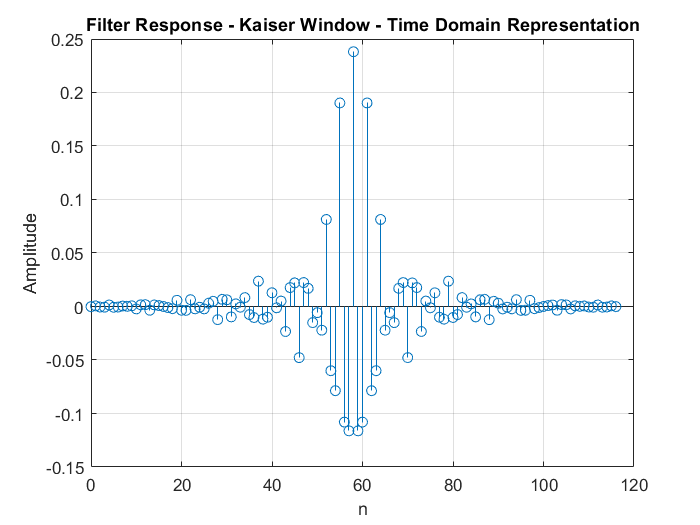

filter = hnt.*wknt;
figure
stem(n_shifted,filter)
grid on;
xlabel('n')
ylabel('Amplitude')
title('Filter Response - Kaiser Window - Time Domain Representation');

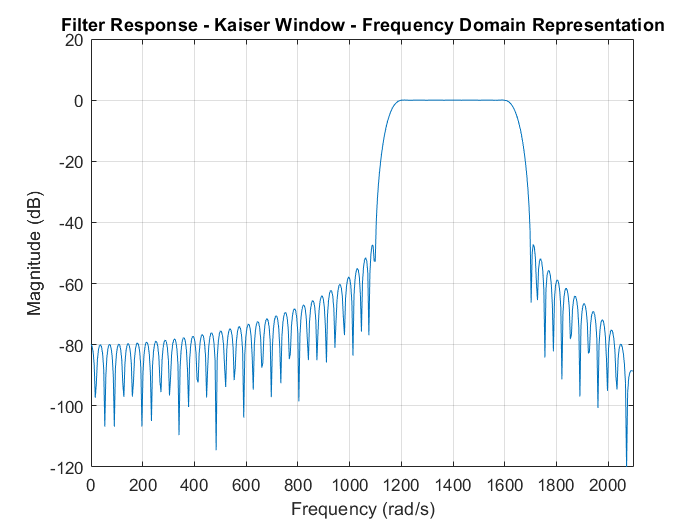


figure
[h,w] = freqz(filter);
w = w/T;
h = 20*log10(abs(h));
plot(w,h)
axis([0,2100,-120,20]);
grid on;
xlabel('Frequency (rad/s)')
ylabel('Magnitude (dB)')
title('Filter Response - Kaiser Window - Frequency Domain Representation');

## Plotting the Passband

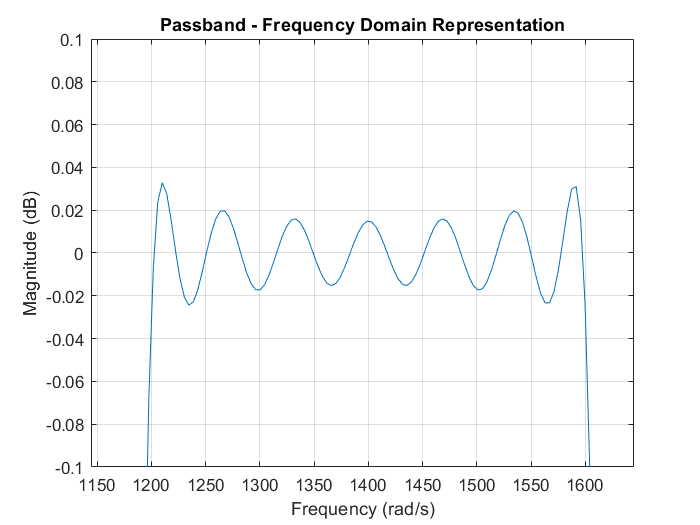

figure
start = round(length(w)/(ws/2)*wc1);
finish = round((length(w)/(ws/2)*wc2));
wpass = w(start:finish);
hpass = (h(start:finish));
plot(wpass,hpass)
grid on;
axis([-inf, inf, -0.1, 0.1]);
xlabel('Frequency (rad/s)')
ylabel('Magnitude (dB)')
title('Passband - Frequency Domain Representation');

## Generation of Input signals

w1 = wc1/2; %component frequencies of the input
w2 = wc1 + (wc2-wc1)/2;
w3 = wc2 + (ws/2-wc2)/2;
wi = [w1,w2,w3];

## Time Domain Representation of the input signal with 10 sample points

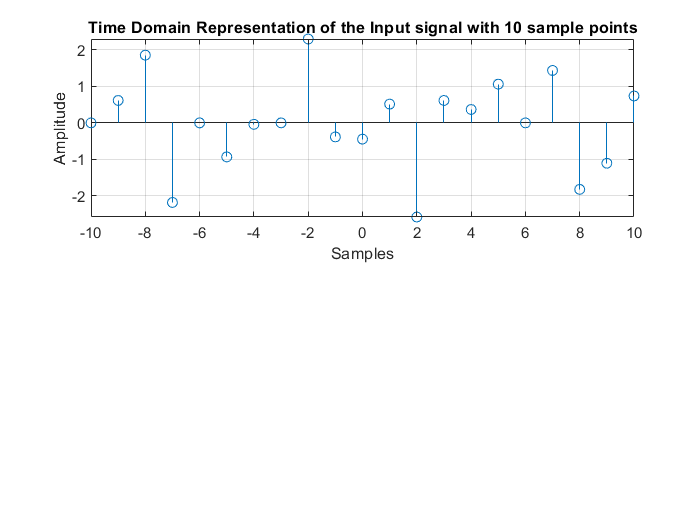

showSamples = 10;
figure
subplot(2, 1, 1)
stem((-showSamples:showSamples), xnt(151-showSamples:151+showSamples))
title('Time Domain Representation of the Input signal with 10 sample points')
xlabel('Samples')
ylabel('Amplitude')
grid on;

## Time Domain Representation of the ideal input signal with mid frequency with 10 sample points

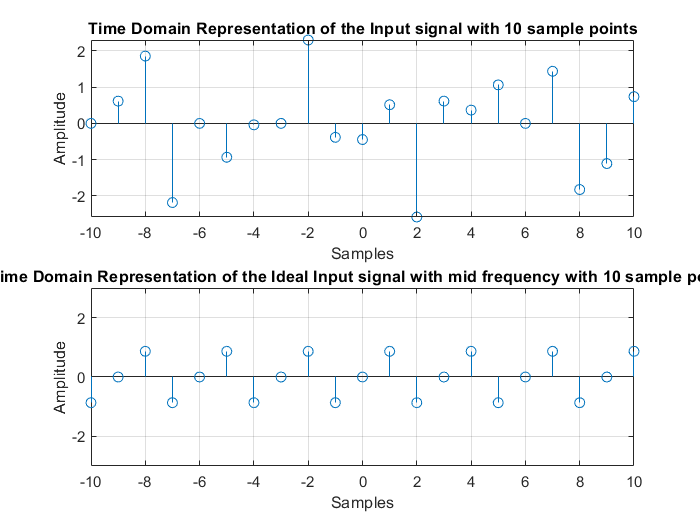

subplot(2, 1, 2)
stem((-showSamples:showSamples), x_out_ideal_filter(151-showSamples:151+showSamples))
title('Time Domain Representation of the Ideal Input signal with mid frequency with 10 sample points')
xlabel('Samples')
ylabel('Amplitude')
ylim([-3 3])
grid on;


n1 = 0:1:300; %x axis for discrete signal
n2 = 0:0.1:300; %x axis for envelope
samples = 301;    

xnt = zeros(1, samples);
x_out_ideal_filter = zeros(1, samples);
for k=1:samples
    n = k - ceil(samples/2);
    nT = n * T;
    xnt(k) = sin(w1 * nT) + sin(w2 * nT) + sin(w3 * nT);
    x_out_ideal_filter(k) = sin(w2 * nT);
end

## Plotting the input signal in Time Domain

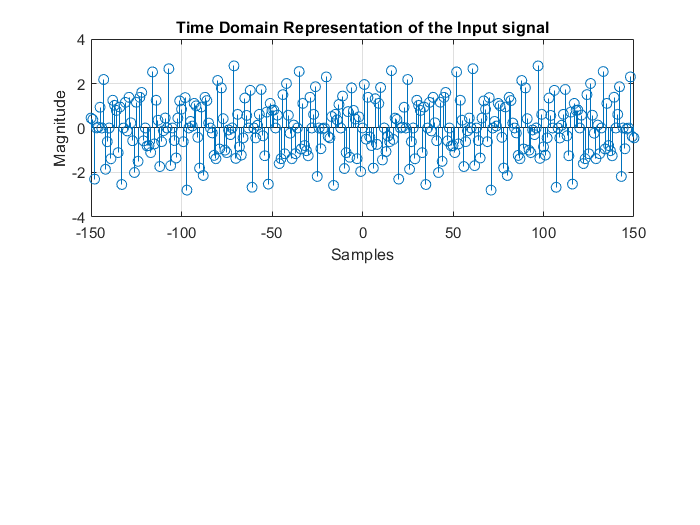

figure, subplot(2, 1, 1)
stem((1-ceil(samples/2):samples-ceil(samples/2)), xnt);
title('Input signal')
ylabel('Magnitude')
xlabel('Samples')
title('Time Domain Representation of the Input signal')
grid on;

## Plotting the ideal input signal in the Time Domain

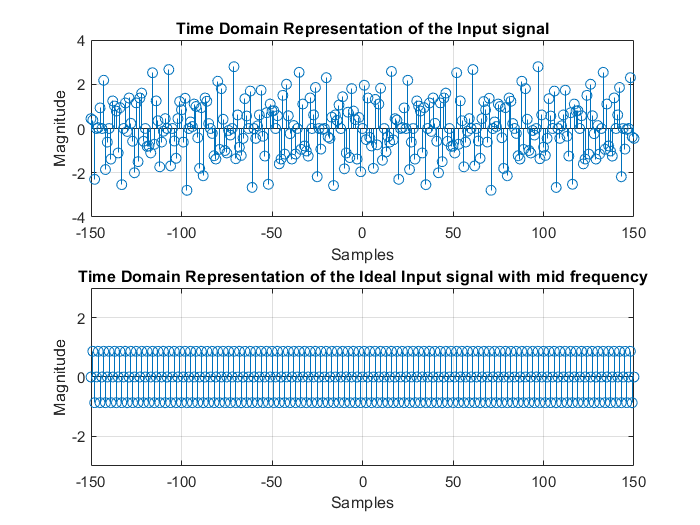

subplot(2, 1, 2)
stem((1-ceil(samples/2):samples-ceil(samples/2)), x_out_ideal_filter);
title('Ideal signal')
ylabel('Magnitude')
xlabel('Samples')
ylim([-3 3])
title('Time Domain Representation of the Ideal Input signal with mid frequency')
grid on;

## Checking the filtering with Discrete Fourier Transform

## Filtering using frequency domain multiplication

xnt = 0;
xdash = 0;
for each = wi                        
    xnt = xnt+ sin(each.*n1.*T); %generate discrete signal
    xdash = xdash+sin(each.*n2.*T); %generate envelope
end
Npoint = length(xnt) + length(filter) - 1; %length for fft in x dimension
xfft = fft(xnt,Npoint);
filterfft = fft(filter,Npoint);
outfft = filterfft .* xfft;
out = ifft(outfft,Npoint);
out1 = out(floor(N/2)+1:length(out)-floor(N/2)); %shifting delay

## Frequency domain representation of input signal

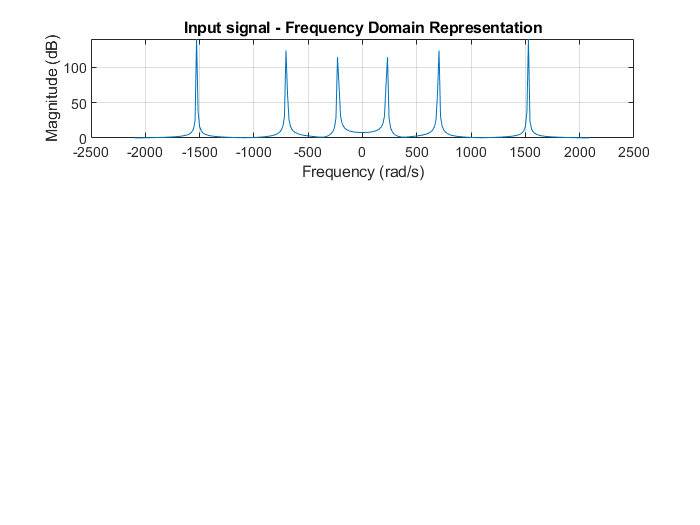

figure 
subplot(3,1,1)
Npoint = length(xnt);  
xfft = fft(xnt,Npoint);
x1 = n1/length(n1)*ws-ws/2;
plot(x1,abs(xfft))
grid on;
xlabel('Frequency (rad/s)')
ylabel('Magnitude (dB)')
title('Input signal - Frequency Domain Representation');

## Frequency domain representation of Output signal from the BPF

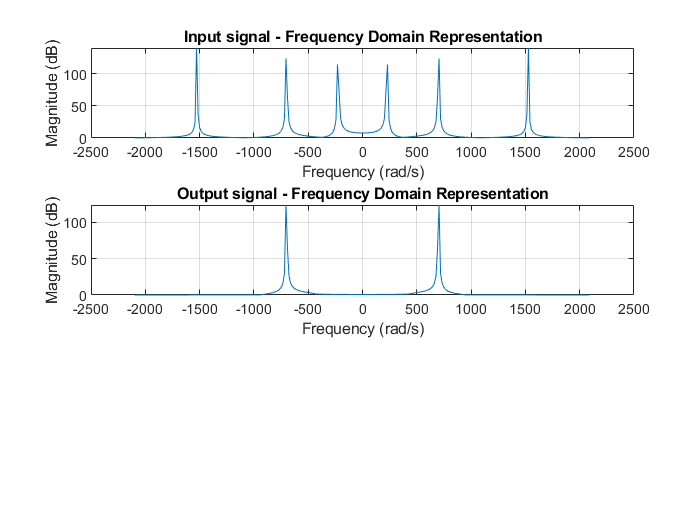

subplot(3,1,2)
Npoint = length(out1);  % length for fft in x dimension
xffout = fft(out1,Npoint);
x1 = n1/length(n1)*ws-ws/2;
plot(x1,abs(xffout))
grid on;
xlabel('Frequency (rad/s)')
ylabel('Magnitude (dB)')
title('Output signal - Frequency Domain Representation');

## Frequency domain representation of Output signal from the ideal BPF

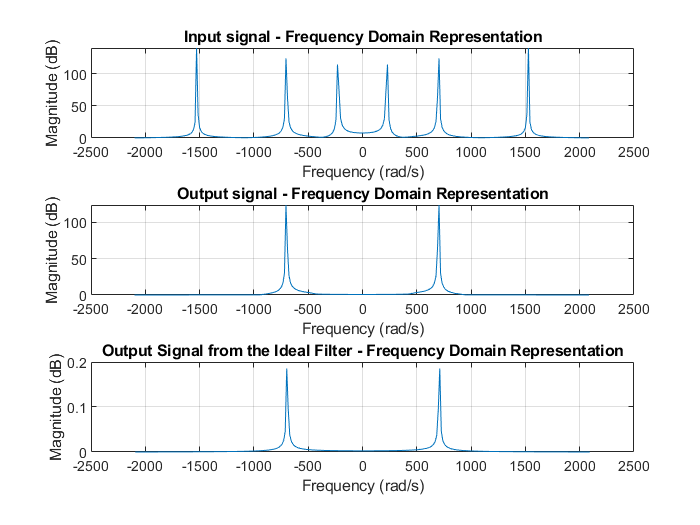

[~, c] = size( abs( fft(x_out_ideal_filter) ) );
y = (-floor(c/2):floor(c/2))/c*w_s;
subplot(3,1,3);
plot(y ,  abs( T*fft(x_out_ideal_filter) ) )
title('Output Signal from the Ideal Filter - Frequency Domain Representation')
ylabel('Magnitude (dB)')
xlabel('Frequency (rad/s)')
grid on;

## time domain representation of input signal

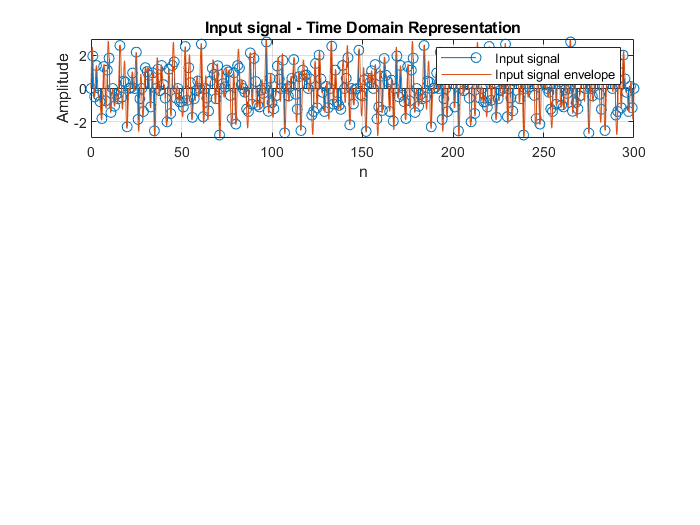

figure
subplot(3,1,1)
stem(n1,xnt)
xlabel('n')
ylabel('Amplitude')
title('Input signal - Time Domain Representation');
hold on 
plot(n2,xdash)
grid on;
legend('Input signal','Input signal envelope');

## Time domain representation of the Output signal from the BPF

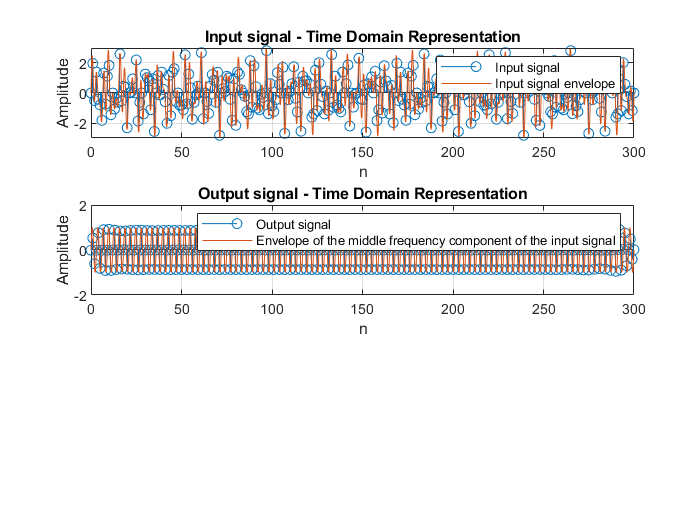

subplot(3,1,2)
stem(n1,out1)
xlabel('n')
ylabel('Amplitude')
title('Output signal - Time Domain Representation');
hold on
plot(n2,sin(w2.*n2.*T))
xlim([0,300])
ylim([-2,2])
grid on;
legend('Output signal','Envelope of the middle frequency component of the input signal');

## Time Domain Representation of the Output signal from the ideal BPF

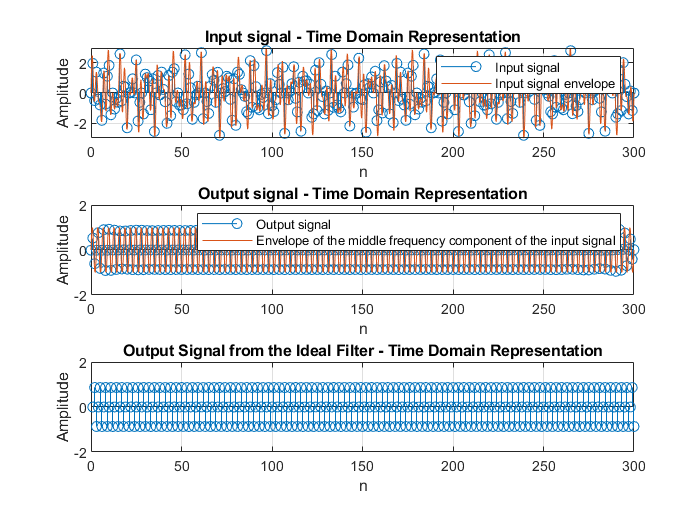

subplot(3,1,3);
stem(x_out_ideal_filter);
title('Output Signal from the Ideal Filter - Time Domain Representation')
ylabel('Amplitude')
xlabel('n')
xlim([0,300])
ylim([-2 2])
grid on;